% Parameters 
A = 100;                % total area (ha)
K_tot = 3000000;        % total carrying capacity (kg)
C = 400;                % cattle number
a = 1e-4;               % grazing efficiency
thr_frac = 0.2;         % threshold fraction to move cattle
Tmax = 365;             % simulation days
dt = 0.05;              % time step (day)

% Dynamic Growth Rate Parameters 
r_max = 0.04;           % maximum intrinsic growth rate (1/day)
alpha = 0.02;           % recovery rate of r (1/day)
beta  = 5e-12;          % baseline grazing-induced reduction
N = 1;                  % single pasture = continuous grazing


%  Dynamic r simulation
[t, G, r, cur, avg_dyn] = simulate(N, r_max, alpha, beta, true, ...
    K_tot, A, C, a, thr_frac, Tmax, dt);

fprintf('Continuous grazing (N = 1):\n');

Continuous grazing (N = 1):


fprintf('  avg biomass (dynamic r) = %.2f kg/ha\n', avg_dyn);

  avg biomass (dynamic r) = 2214.58 kg/ha


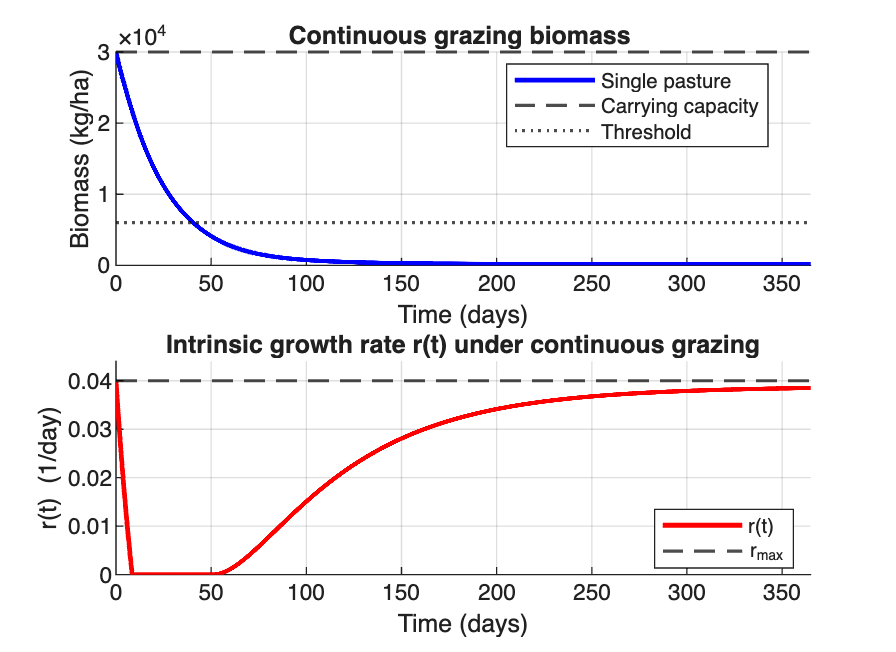


K_i = K_tot / N;
A_i = A / N;

% Plot biomass and r(t) 
figure('Name','Continuous grazing (N = 1)','Position',[100 100 1100 800]);

% Biomass 
subplot(2,1,1); hold on;
h = plot(t, G(:,1)/A_i, 'b-', 'LineWidth', 1.8);
hK = yline(K_i/A_i, 'k--', 'LineWidth', 1.2);
hT = yline(thr_frac*K_i/A_i, 'k:', 'LineWidth', 1.2);

xlabel('Time (days)');
ylabel('Biomass (kg/ha)');
title(sprintf('Continuous grazing biomass '));

legend([h; hK; hT], ...
       {'Single pasture','Carrying capacity','Threshold'}, ...
       'Location','best');
grid on; xlim([0 Tmax]);

%  r(t) 
subplot(2,1,2); hold on;
hr = plot(t, r(:,1), 'r-', 'LineWidth', 1.8);
hRmax = yline(r_max, 'k--', 'LineWidth', 1.2);

xlabel('Time (days)');
ylabel('r(t)  (1/day)');
title('Intrinsic growth rate r(t) under continuous grazing');

legend([hr; hRmax], {'r(t)','r_{max}'}, 'Location','best');
grid on; xlim([0 Tmax]); ylim([0 r_max*1.1]);



% Comparing constant verses dynamic r 
fprintf('\n CONSTANT vs DYNAMIC r (N = 1)\n');


 CONSTANT vs DYNAMIC r (N = 1)



[~,~,~,~,avg_const] = simulate(N, r_max, alpha, beta, false, ...
    K_tot, A, C, a, thr_frac, Tmax, dt);

fprintf('Constant r : %.2f kg/ha\n', avg_const);

Constant r : 5640.03 kg/ha


fprintf('Dynamic  r : %.2f kg/ha\n', avg_dyn);

Dynamic  r : 2214.58 kg/ha


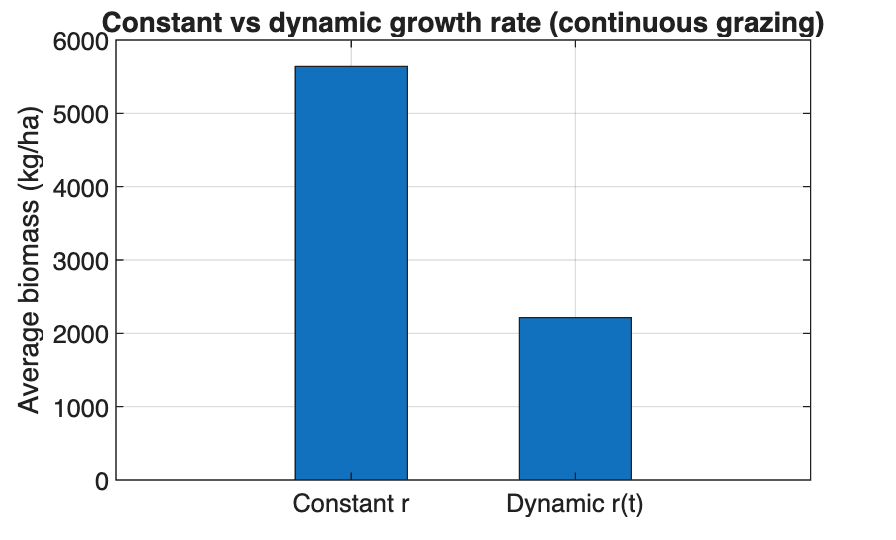


figure('Name','Constant vs dynamic r (N = 1)');
bar([1 2], [avg_const, avg_dyn], 0.5);
set(gca, 'XTick', [1 2], 'XTickLabel', {'Constant r','Dynamic r(t)'});
ylabel('Average biomass (kg/ha)');
title('Constant vs dynamic growth rate (continuous grazing)');
grid on;



%  Local simulation 
function [t_h, G_h, r_h, cur_h, avg_ha] = simulate(...
    N, r_max, alpha, beta, use_dynamic_r, ...
    K_tot, A, C, a, thr_frac, Tmax, dt)

    K_i = K_tot / N;
    G = K_i * ones(1, N);
    r = r_max * ones(1, N);
    t = 0; current = 1;
    
    nsteps = ceil(Tmax/dt);
    t_h   = zeros(nsteps,1);
    G_h   = zeros(nsteps, N);
    r_h   = zeros(nsteps, N);
    cur_h = zeros(nsteps, 1);
    idx   = 1;
    
    while t < Tmax
        I = zeros(1,N); I(current) = 1;
        for i = 1:N
            dG = r(i)*G(i)*(1 - G(i)/K_i) - I(i)*G(i)*C*a;
            if use_dynamic_r
                dr = alpha*(r_max - r(i)) - beta*I(i)*G(i)*C;
                r(i) = max(0, r(i) + dr*dt);
            end
            G(i) = max(0, G(i) + dG*dt);
        end
        t = t + dt;
        t_h(idx)   = t;
        G_h(idx,:) = G;
        r_h(idx,:) = r;
        cur_h(idx) = current;
        idx = idx + 1;
        if G(current) < thr_frac*K_i
            current = mod(current, N) + 1;
        end
    end
    t_h   = t_h(1:idx-1);
    G_h   = G_h(1:idx-1,:);
    r_h   = r_h(1:idx-1,:);
    cur_h = cur_h(1:idx-1);
    avg_ha = mean(sum(G_h,2))/A;
end